# Parte 1

# 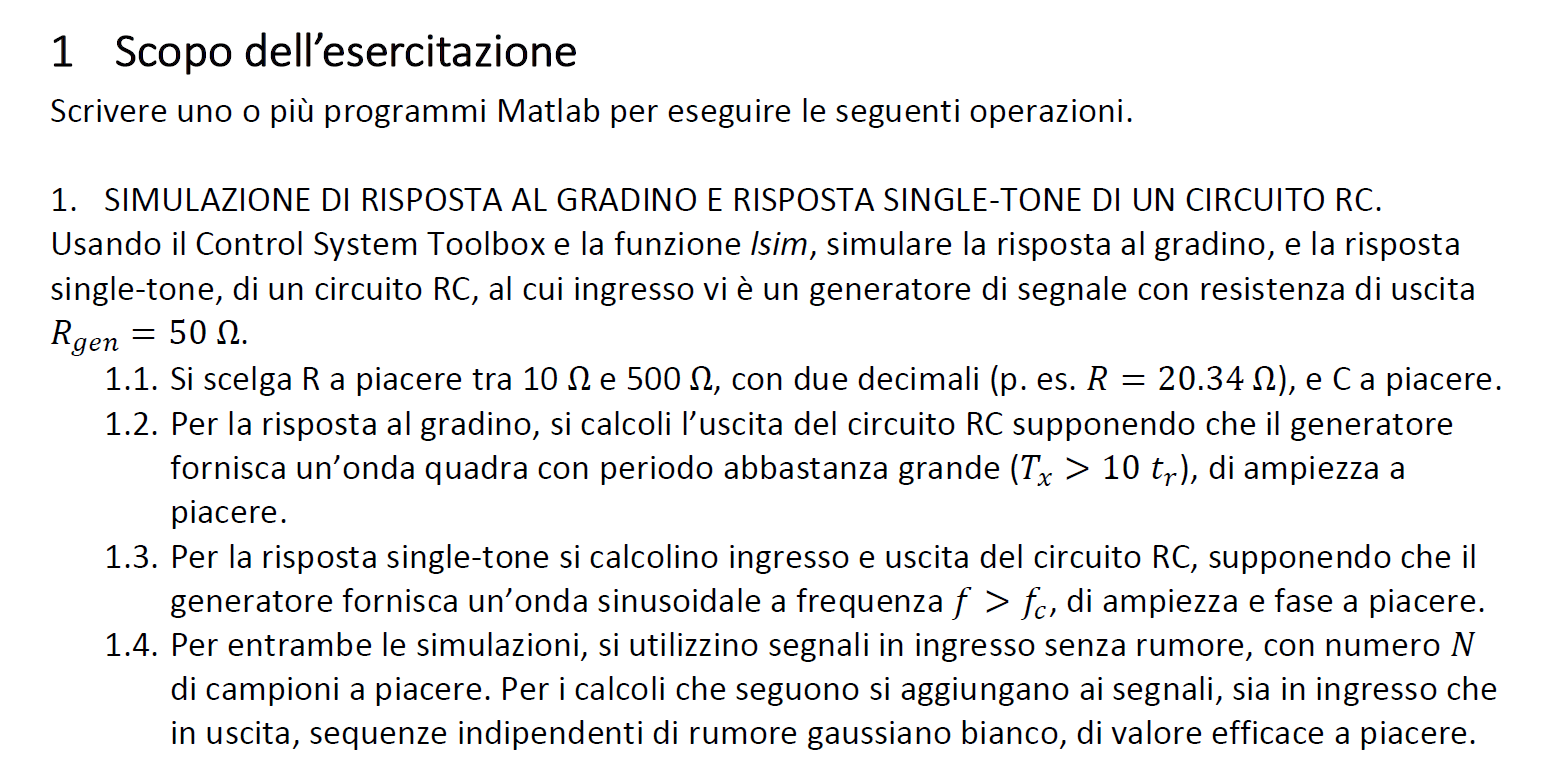

## 1.1

Rgen = 50;
R = 74.38;
C = 15e-9;

tr = C*(Rgen + R)*log(9)

tr =    4.0994e-06



N = 1000;
tau_step = R*C

tau_step =    1.1157e-06


## 1.2


Tx = 10*tr

Tx =    4.0994e-05



Vpp = 10; %ampiezza del gradino

Ts = Tx/N % periodo di campionamento

Ts =    4.0994e-08



n = (0:N-1)'; %indici dei campioni

t = n*Ts; %istanti di campionamento


## generazione forma d'onda

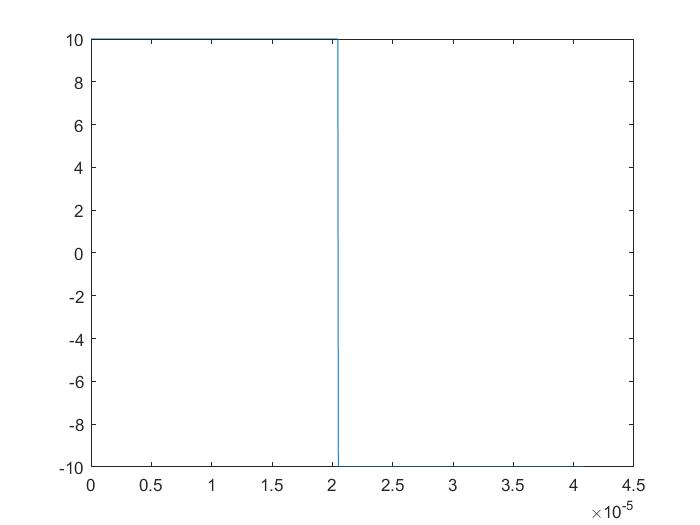

wt = 2*pi*t/Tx;
x_step = Vpp*square(wt);

figure(1)
plot(t, x_step)

## simulazione risposta all'onda quadra


s = tf('s');

H1_dot = 1/(1+s*tau_step)


H1_dot =
 
         1
  ---------------
  1.116e-06 s + 1
 
Continuous-time transfer function.



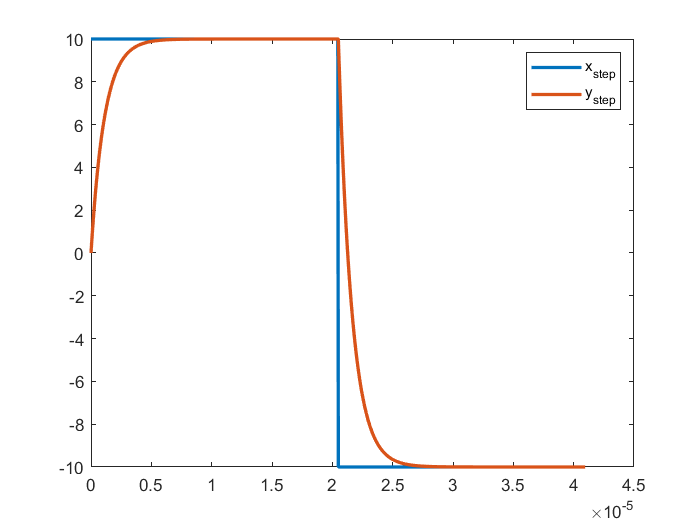


y_step = lsim(H1_dot, x_step, t);

figure(1)
plot(t, x_step, t, y_step, 'linewidth', 2)

legend('x_{step}', 'y_{step}')

## 1.3

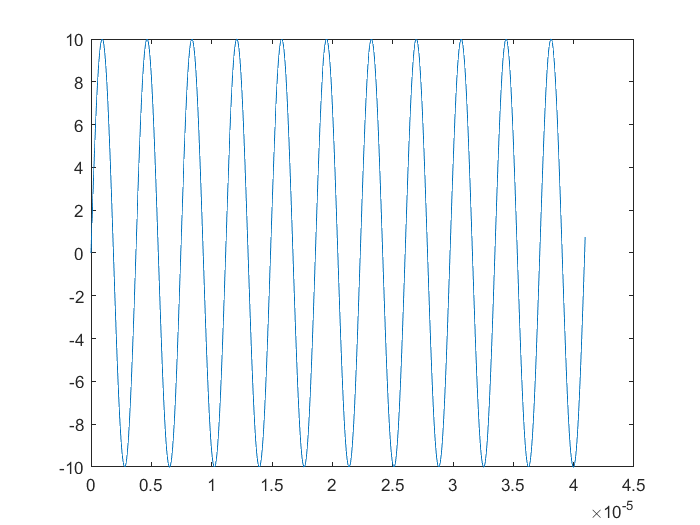

tau_sin = 10*(R+Rgen)*C;

Np = 3;

Tx = (10*tau_step)/Np;

f = 1/Tx;

wt = 2*pi*f*t;

x_sin = Vpp*sin(wt);

figure(1)
plot(t, x_sin)

## risposta alla sinusoide single tone

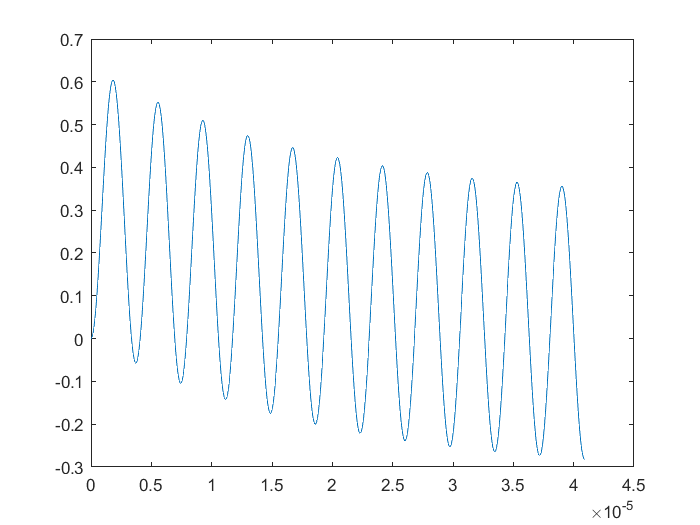

H_dot = (1/(1+tau_sin*s));

y_sin = lsim(H_dot, x_sin, t);

figure(1)
plot(t, y_sin)